Plot timecourse for cell 1/305...


Plot timecourse for cell 2/305...


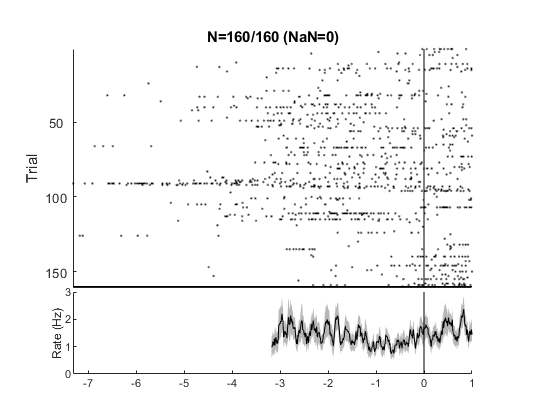

Plot timecourse for cell 3/305...


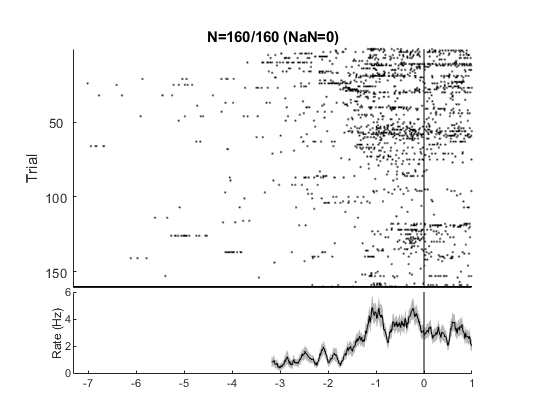

Plot timecourse for cell 4/305...


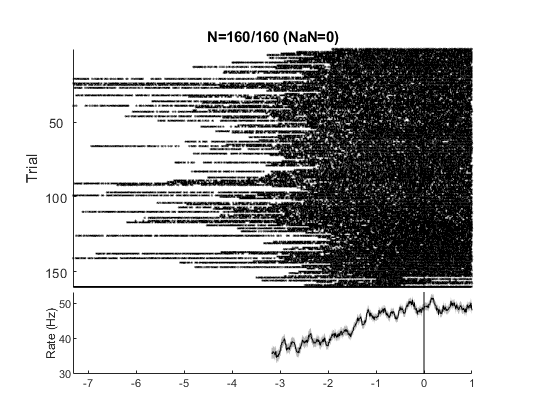

Plot timecourse for cell 5/305...


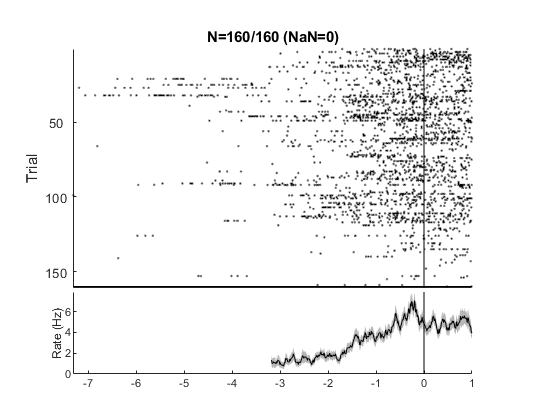

Plot timecourse for cell 6/305...


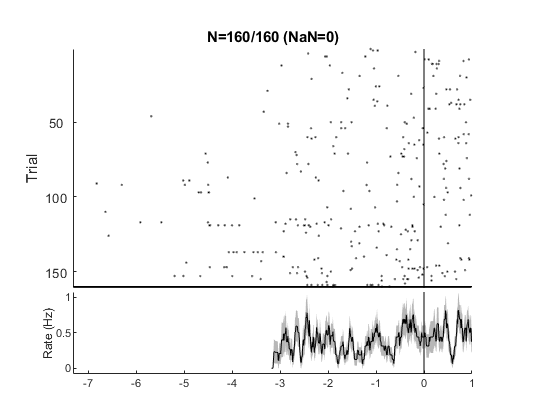

Plot timecourse for cell 7/305...


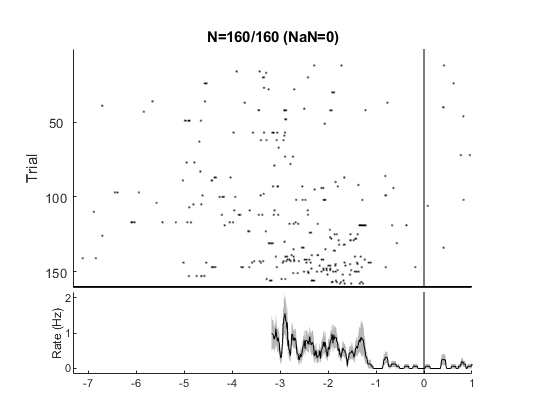

Plot timecourse for cell 8/305...


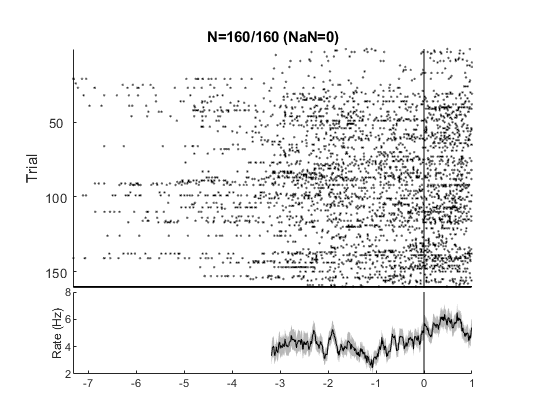

Plot timecourse for cell 9/305...


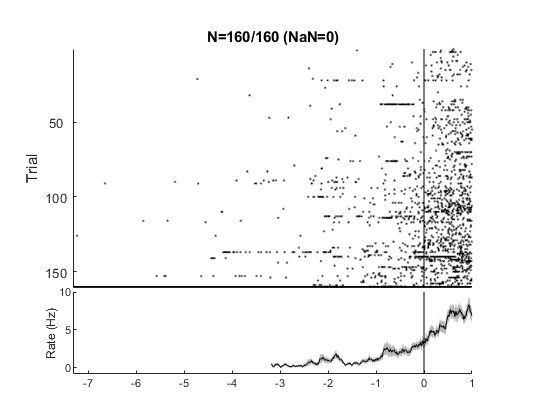

Plot timecourse for cell 10/305...


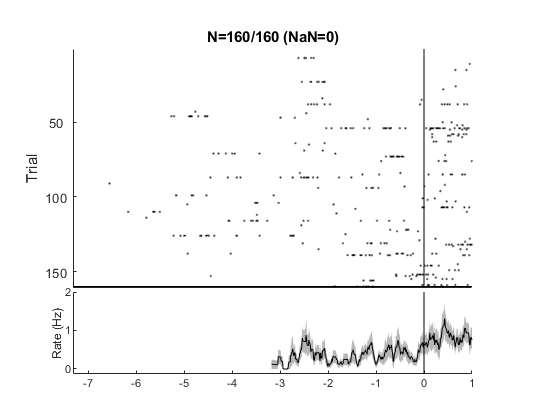

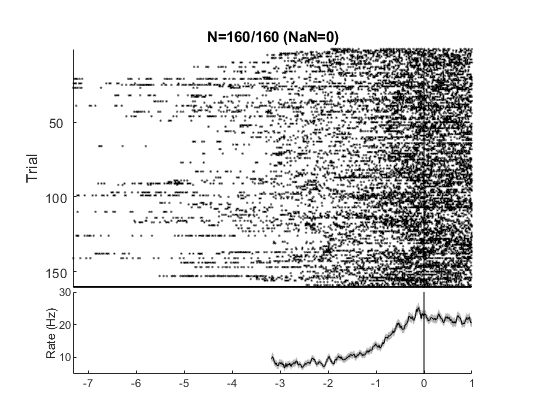

paths = struct;
paths.data = 'C:\Users\malcg\Dropbox (Personal)\UchidaLab\processed_neuropix_data';

opt = struct;
opt.session = '80_20200317.mat';

addpath(genpath('C:\code\HGRK_analysis_tools'));


% load data
load(fullfile(paths.data,opt.session));

% plot timecourse
% plot_timecourse('timestamp', lick, event.REWARD_CD, event.TRIAL_START_CD, event.TRIAL_END_CD);
good_cells = sp.cids(sp.cgs==2);
patchstop_ms = patchCSL(:,2)*1000;
patchleave_ms = patchCSL(:,3)*1000;
psth_all = nan(numel(good_cells),1603);
for i = 1:10 % numel(good_cells)
    fprintf('Plot timecourse for cell %d/%d...\n',i,numel(good_cells));
    spiket = sp.st(sp.clu==good_cells(i));
    spiket_ms = spiket*1000;
    h = figure;
    [~,~,z]=plot_timecourse('timestamp',spiket_ms,patchleave_ms,patchstop_ms,patchleave_ms+1000);
    psth_all(i,:) = z.mean;
end

## pca

% z score
psth_all_clipped = psth_all(:,1185:end);
psth_all_zscore = (psth_all_clipped-nanmean(psth_all_clipped,2))./repmat(nanstd(psth_all_clipped,[],2),1,size(psth_all_clipped,2));
[coeffs,score,~,~,expl] = pca(psth_all_zscore);
plot(expl,'ro');

% project into pca space
pca_proj = coeffs(:,1:2)'*psth_all_zscore';

% 
figure;
plot(pca_proj(1,:),pca_proj(2,:),'ko')